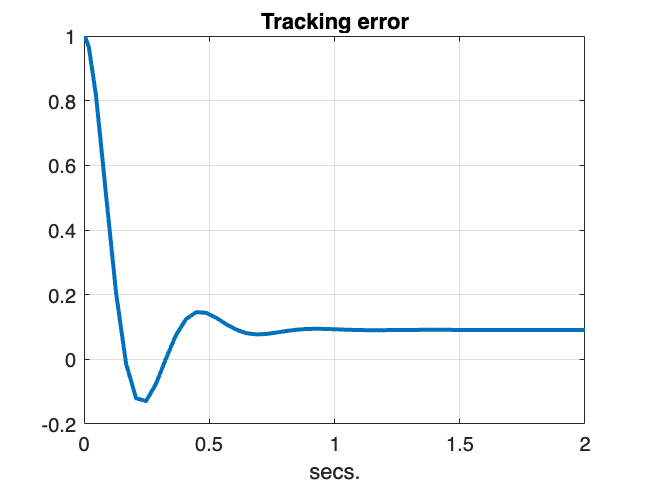

clear;
close all;

% numerical parameters of the motor

J=0.01; b=0.1; Km=0.01; R=1; L=0.5;

% matrices A, B, C, D

A = [-R/L -Km/L;
     Km/J -b/J];

B = [1/L; 0];

C = [0 1];

D = 0;

DCMotor = ss(A,B,C,D);

% gain of the proportional controller

K=100;

% final simulation time

tfin = 2;

result=sim("dc_p_control.slx", tfin);

% depict the tracking error

plot(result.tout, result.error, LineWidth=2);
grid;
title('Tracking error');
xlabel('secs.');


% numerical deviation of the steady state tracking error

e_inf=result.error(end)

e_inf = 0.0910